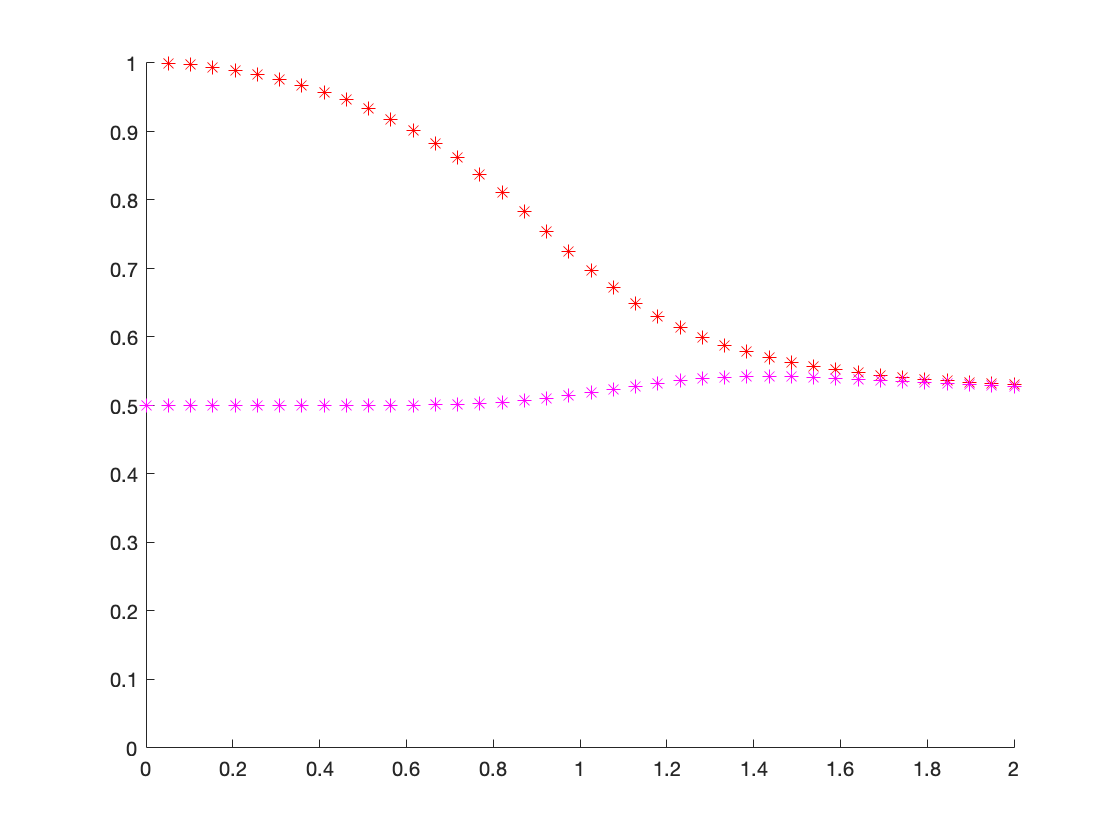












% TFIM with Z transverse field
% assuming the ZZ coupling is normalized to 1 J = 1
gz = 0.1;
N = 8;

% consistency check with vbb2023
ghz1 = zeros(2^N,1); % GHZ^-
ghz1(1) = 1/sqrt(2);
ghz1(end) = -1/sqrt(2);
ghz0 = zeros(2^N,1); % GHZ^+
ghz0(1) = 1/sqrt(2);
ghz0(end) = 1/sqrt(2);

gxset = linspace(0,2,40);
p0 = zeros(1,40); p1 = zeros(1,40);
for i = 1:40
    [~,~,spec,~] = edTFIM(0,gxset(i),N);
    GS = spec(:,1);
    p0(i) = 1/2*(1+norm(GS'*ghz0)^2-norm(GS'*ghz1)^2);
    [~,~,spec,~] = edTFIM(0.1,gxset(i),N);
    GS = spec(:,1);
    p1(i) = 1/2*(1+norm(GS'*ghz0)^2-norm(GS'*ghz1)^2);
end

figure()
hold on
scatter(gxset,p0,'r*')
scatter(gxset,p1,'m*')
hold off
ylim([0,1])

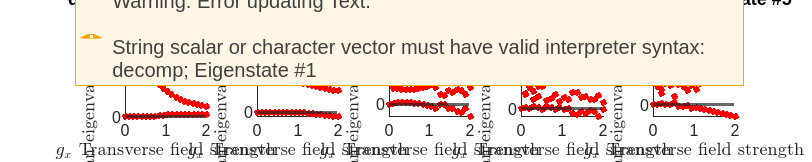

% compute hessian


% modification Wed 11 Oct 22:25
% the system need not be translation invariant. Hence we may need to plot
% all 6 eigenstates Hessian spectrum.
tic
n = 20;

gxset = linspace(0,2,n);
N = 7;

n1 = 2^N;


[X1,Y1,Z1] = PauliM(N,1);
sigmas = {X1,Y1,Z1};
[X2,Y2,Z2] = PauliM(N,2);

X = [0,1;1,0];
Y = 1i * [0,-1;1,0];
Z = [1,0;0,-1];

E = zeros(1,n1);
I = eye(2);
% the 3-by-3 Hessian spectrum
% n: the position on the phase space
% n1: label of the n1^th eigenstate
Ms = zeros(3,3,n,n1);
Ms1 = zeros(3,3,n,n1);


gzset = [0];

eigspecFull = zeros(3*n1,n,length(gzset));
colors = [linspace(0,1,length(gzset));zeros(size(gzset));linspace(1,0,length(gzset))];
colors = colors.';
colors = eye(3); % RGB
MarkFaceAlphas = linspace(0.2,1,length(gzset));
flagLocalHamiltonian = 'decomp';

for igz = 1:length(gzset)
    gz = gzset(igz);
    
    Hloc = zeros(2^N);
    
    switch flagLocalHamiltonian
        case 'decomp' % prioritizing that local terms sums to total H
            h = 1;
            for i = 1:N
                % ZNZ1
                if and(i~=N,i~=1)
                    h = kron(h,I);
                else
                    h = kron(h,Z);
                end
            end
            Hloc = Hloc-1/2*h;
            h = 1;
            for i = 1:N
                % Z1Z2
                if and(i~=2,i~=1)
                    h = kron(h,I);
                else
                    h = kron(h,Z);
                end
            end
            Hloc = Hloc-1/2*h;
            
        case 'canonical' % proproritizing that eigenstates are NE
            h = 1;
            for i = 1:N    
                % ZNZ1
                if and(i~=N,i~=1)
                    h = kron(h,I);
                else
                    h = kron(h,Z);
                end
            end
            Hloc = Hloc-h;
            h = 1;
            for i = 1:N    
                % Z1Z2
                if and(i~=2,i~=1)
                    h = kron(h,I);
                else
                    h = kron(h,Z);
                end
            end
            Hloc = Hloc-h;
            
    end
    
    h = 1;
    for i = 1:N     
        % longitudinal term
        if i~=1
            h = kron(h,I);
        else
            h = kron(h,Z);
        end
    end
    Hloc = Hloc-gz*h;

     
    for i = 1:n
        [H,H1,spec,lam] = edTFIM(gz,gxset(i),N);
        
        % local Hamiltonian
        % Hloc = -1/2*(kron(kron(I,Z),Z)+kron(kron(Z,Z),I))-gz*kron(kron(I,Z),I)-gxset(i)*kron(kron(I,X),I);
        
        % local Hamiltonian at site=1
        % add x transverse field
        h = 1;
        for j = 1:N
            if j~=1
                h = kron(h,I);
            else
                h = kron(h,X);
            end
        end
        Hloc1 = Hloc-gxset(i)*h;
        
        
        
        
        for j = 1:n1
            E(j) = lam(j);
            vec = spec(:,j);
            
            
            for al = 1:3
                sigmaa = sigmas{al};
                
                % check that the 1st order derivatives vanish
                % so that the state is indeed a Nash extreme
                assert(norm(vec'*(H*sigmaa-sigmaa*H)*vec)<1e-7, ...
                    'state not stationery wrt global Hamiltonian')
               
                
                assert(norm(vec'*(Hloc1*sigmaa-sigmaa*Hloc1)*vec)<1e-7, ...
                    'state not stationery wrt local Hamiltonian')

                for be = 1:3
                    sigmab = sigmas{be};        
                    
                    Ms(al,be,i,j) = vec'*sigmaa*(H-E(j)*eye(2^N))*sigmab*vec;
                    % above formula does not give the correct Hessian if the
                    % Hamiltonian consists of not only k-local terms
                    %op = 2*sigmaa*Hloc*sigmab - sigmaa*sigmab*Hloc - Hloc*sigmaa*sigmab;

                    Ms1(al,be,i,j) = vec'*(2*sigmaa*Hloc1*sigmab - sigmaa*sigmab*Hloc1 - Hloc1*sigmaa*sigmab)*vec;
                    
                end
            end
        end
    end
        
    % consider the spectrum of the Hessian
    eigspec = zeros(3*n1,n);
    for i = 1:n
        A = [];
        for j = 1:n1
            M = Ms(:,:,i,j);
            [~,eigvals] = eig(M,"vector");
            A = [A;real(eigvals)];
            % sort the eigenvalues
        end
        eigspec(:,i) = A;
    end
    
    eigspecFull(:,:,igz) = eigspec;
end

nplot = 5;
stateplot = [1,2,3,4,5];
figure('Position',[500,500,400*nplot,400]);
colors = eye(3);
hold on
for i = 1:nplot
    subplot(1,nplot,i);
    hold on
    for igz = 1:length(gzset)
        eigspec = eigspecFull(:,:,igz);
        plot(gxset,eigspec(3*(stateplot(i)-1)+1,:),'Marker','o','MarkerSize',5,'LineStyle',"none", ...
            'Color',colors(igz,:),'MarkerFaceColor',colors(igz,:),'DisplayName',['$g_z=$ ',num2str(gzset(igz))]);
        plot(gxset,eigspec(3*(stateplot(i)-1)+2:3*stateplot(i),:),'Marker','o','MarkerSize',5,'LineStyle',"none", ...
            'Color',colors(igz,:),'MarkerFaceColor',colors(igz,:),'HandleVisibility','off');
    end
    yline(0,'LineWidth',1.7,'HandleVisibility','off')
    xlabel('$g_x$ Transverse field strength','Interpreter',"latex")
    ylabel('Hessian eigenvalue spectrum of $M_{\alpha \beta}$','Interpreter',"latex");
    % ylim([-2,10]);
    legend('Interpreter','latex');
    title([flagLocalHamiltonian,'; Eigenstate #',num2str(stateplot(i))]);
    hold off
end

toc

Elapsed time is 23.103502 seconds.


% [H,H1,spec,lam] = edTFIM(0.1,0.9,6);
% H0 = zeros(2^6);
% for i = 1:6
%     H0 = H0 + H1(:,:,i);
% end
% assert(isequal(H,H0),'local does not sum to global Hamiltonian')
% 
% z12 = tprod(Z,Z,I,I,I,I);
% zn1 = tprod(Z,I,I,I,I,Z);
% 
% x1 = tprod(X,I,I,I,I,I);
% z1 = tprod(Z,I,I,I,I,I);
% 
% h1cano = -z12-zn1-gxset(2)*x1-gz*z1;
% [H,H1,spec,lam] = edTFIM(gz,gxset(2),6);
% 
% isequal(h1cano,Hloc1)

% [H,H1,spec,lam] = edTFIM(0.1,0.9,6);
% H0 = zeros(2^6);
% for i = 1:6
%     H0 = H0 + H1(:,:,i);
% end
% assert(isequal(H,H0),'local does not sum to global Hamiltonian')
% 
% z12 = tprod(Z,Z,I,I,I,I);
% zn1 = tprod(Z,I,I,I,I,Z);
% 
% x1 = tprod(X,I,I,I,I,I);
% z1 = tprod(Z,I,I,I,I,I);
% 
% h1cano = -z12-zn1-gxset(2)*x1-gz*z1;
% [H,H1,spec,lam] = edTFIM(gz,gxset(2),6);
% 
% isequal(h1cano,Hloc1)


% % Least square methods in finding Nash equilibria
% gz = 1;
% gx = 2;
% N = 3;
% K1 = zeros(2^N);
% K2 = zeros(2^N);
% K3 = zeros(2^N);
% % local Hamiltonian
% [Hloc,~,~] = edTFIM(gz,gx,N);
% 
% G = cell(3,N);
% 
% for i = 1:N
%     Hi = Hloc(:,:,i);
%     [Xi,Yi,Zi] = PauliM(N,i);
%     K1 = K1 + comm(Xi,Hi)*comm(Xi,Hi)';
%     K2 = K2 + comm(Yi,Hi)*comm(Yi,Hi)';
%     K3 = K3 + comm(Zi,Hi)*comm(Zi,Hi)';
%     G{1,i} = 1i*comm(Xi,Hi);
%     G{2,i} = 1i*comm(Yi,Hi);
%     G{3,i} = 1i*comm(Zi,Hi);
% end
% 
% [spec,lam] = eig(K1,'vector');
% 
% [a,b] = eig(G{2,3}*G{2,3}')
% G{2,3}*G{2,3}'


function [H,Hloc,spec,lam] = edTFIM(gz,gx,N)

X = [0,1;1,0];
Y = 1i * [0,-1;1,0];
Z = [1,0;0,-1];
I = eye(2);


H = zeros(2^N);
Hloc = zeros(2^N,2^N,N);
for i = 1:N
    Hi = zeros(2^N);
    
    % periodic boundary condition
    if i == N
        j = 1;
    else
        j = i+1;
    end
    
    % the ZZ term
    h = 1;
    for k = 1:N
        if and(k~=i,k~=j)
            h = kron(h,I);
        else
            h = kron(h,Z);
        end
    end
    Hi = Hi-h;
    
    % the X transverse field
    h = 1;
    for k = 1:N
        if k~=i
            h = kron(h,I);
        else
            h = kron(h,X);
        end
    end
    Hi = Hi-h*gx;
    
    % the Z transverse field
    h = 1;
    for k = 1:N
        if k~=i
            h = kron(h,I);
        else
            h = kron(h,Z);
        end
    end
    Hi = Hi-h*gz;
    
    H = H + Hi;
    Hloc(:,:,i) = Hi;
end

[spec,lam] = eig(H,'vector');

end


function [Xi,Yi,Zi] = PauliM(N,i)
X = [0,1;1,0];
Y = 1i * [0,-1;1,0];
Z = [1,0;0,-1];
I = eye(2);

Xi = 1;
Yi = 1;
Zi = 1;
for j = 1:N
    if j~=i
        Xi = kron(Xi,I);
        Yi = kron(Yi,I);
        Zi = kron(Zi,I);
    else
        Xi = kron(Xi,X);
        Yi = kron(Yi,Y);
        Zi = kron(Zi,Z);
    end
end

end

function A = comm(B,C)
A = B*C-C*B;
end

function A = tprod(varargin)
A = varargin{1};
for k = 2:nargin
     A = kron(A, varargin{k});
end
end